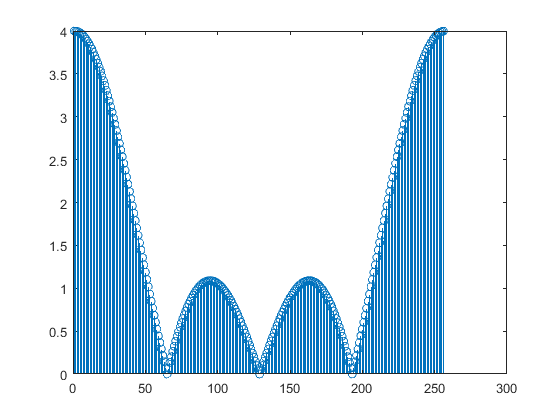

x = [1 1 1 1];
Xk = dft(x, 256);
stem(abs(Xk))

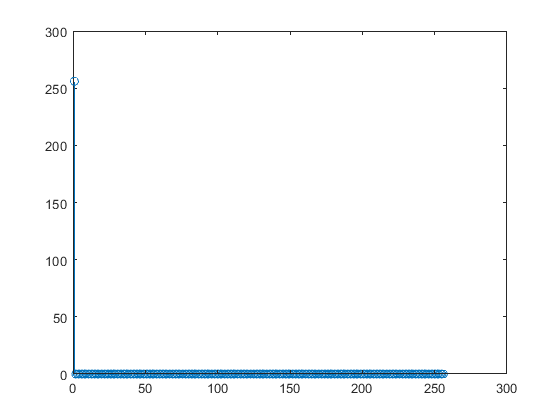

x2 = ones(1,256);
Xk2 = dft(x2,256);
stem(abs(Xk2))

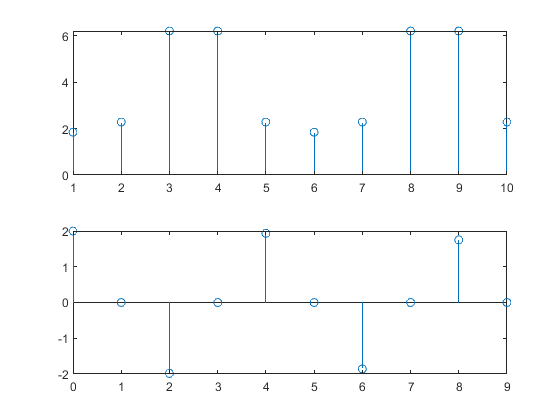

n = 0:1:9;
xn = cos(0.48*pi*n) + cos(0.52*pi*n);
stem(n,xn)
Xk10 = dft(xn,10);
subplot(2,1,1);
stem(abs(Xk10));

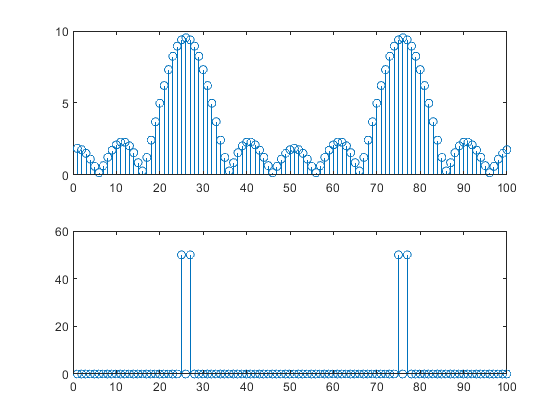

Xk100p = dft(xn,100);
figure;
subplot(2,1,1);
stem(abs(Xk100p));
n100 = 0:1:99;
xn100 = cos(0.48*pi*n100) + cos(0.52*pi*n100);
Xk100 = dft(xn100,100);
subplot(2,1,2);
stem(abs(Xk100));

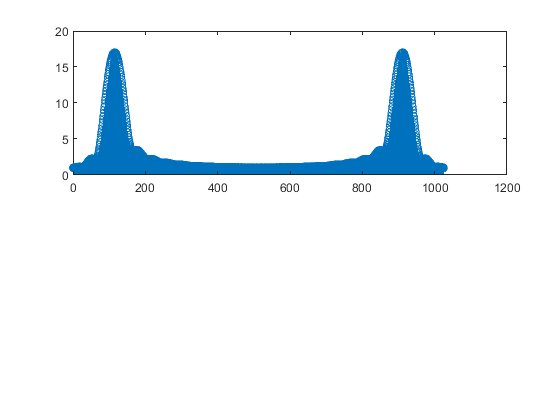

Fs = 100;
Ts = 1/Fs;
N = 26;
n = 0:1:N-1;
xn = cos(2*pi*10*n*Ts) + cos(2*pi*12*n*Ts);
Xk26 = dft(xn, 1024);
subplot(2,1,1)
stem(abs(Xk26));

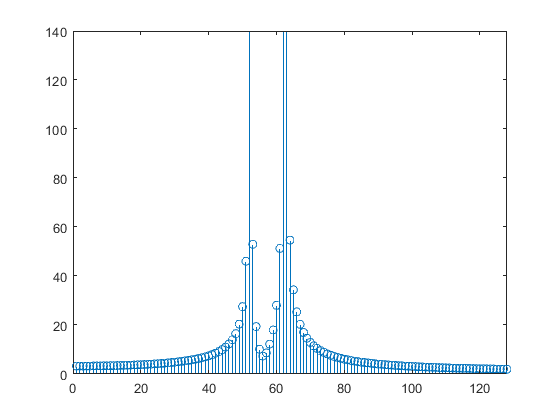


N2 = 512;
n2 = 0:1:N2-1;
xn101 = cos(2*pi*10*n2*Ts) + cos(2*pi*12*n2*Ts);
Xk101 = dft(xn101, N2);
figure;
stem(abs(Xk101));
axis([0 N2/4 0 140])